% problem a
syms z K T
num = K*T;
den = z - 1;
sys_a = num / den

$$sys\_a = \frac{K\,T}{z-1}$$

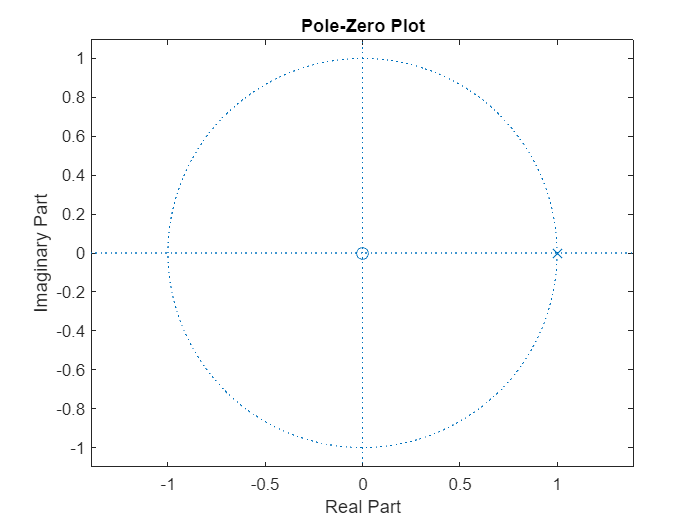

zeros_a = 0;
poles_a = 1;
% T가 0.5 또는 0.05에 따라서 pole과 zero의 위치가 변하지 않는다.
zplane(zeros_a, poles_a)

% problem b
num = (3*T + 1 - z)*(z - exp(-3*T)) + (z - 1^2);
den = 3*(z - 1)*(z - exp(-3*T));
sys = simplifyFraction(num / den)

$$sys = -\frac{3\,T-z+{\mathrm{e}}^{3\,T}+z^{2}\,{\mathrm{e}}^{3\,T}-2\,z\,{\mathrm{e}}^{3\,T}-3\,T\,z\,{\mathrm{e}}^{3\,T}+1}{3\,\left(z\,{\mathrm{e}}^{3\,T}-1\right)\,\left(z-1\right)}$$

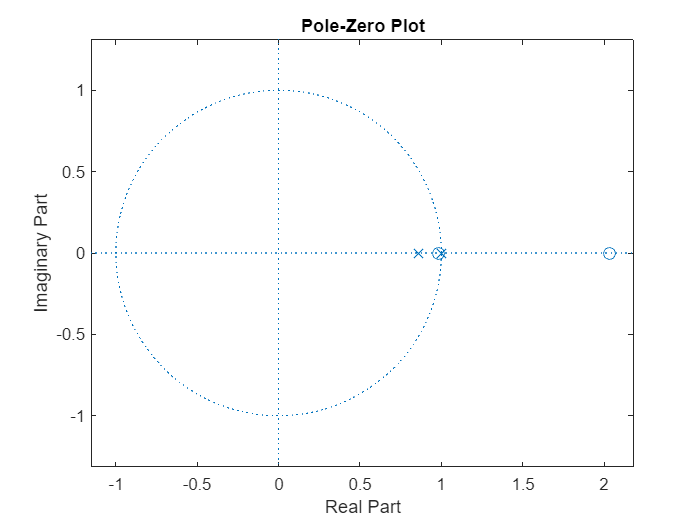

sys_b1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_b1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

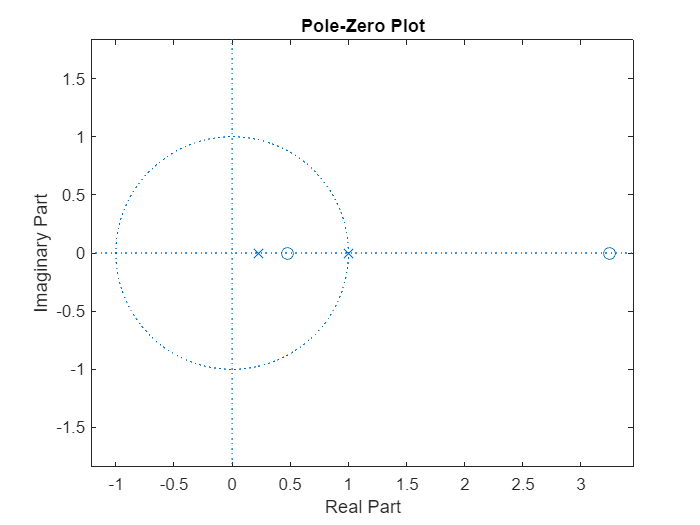

sys_b2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_b2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

% problem c
num = 2*(z - exp(-T))*(z - exp(-3*T)) - 3*(z - 1)*(z - exp(-3*T)) + (z - 1)*(z - exp(-T));
den = 2*(z - exp(-T))*(z - exp(-3*T));
sys = num / den

$$sys = \frac{\left(z-{\mathrm{e}}^{-3\,T}\right)\,\left(2\,z-2\,{\mathrm{e}}^{-T}\right)+\left(z-{\mathrm{e}}^{-T}\right)\,\left(z-1\right)-\left(3\,z-3\right)\,\left(z-{\mathrm{e}}^{-3\,T}\right)}{\left(z-{\mathrm{e}}^{-3\,T}\right)\,\left(2\,z-2\,{\mathrm{e}}^{-T}\right)}$$

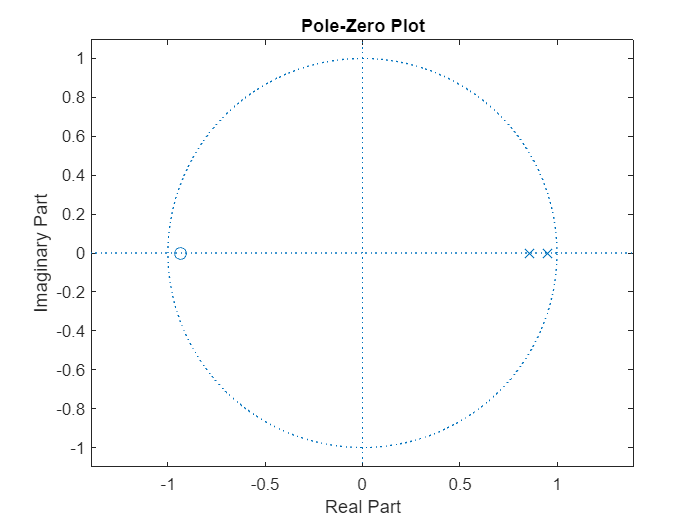

sys_c1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_c1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

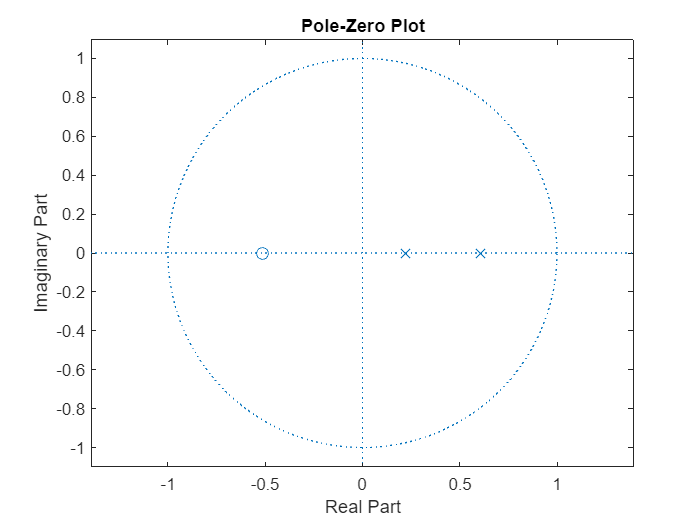

sys_c2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_c2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

% problem d
num = 2*T*(z - 1) + T^2*(z + 1);
den = 2*(z - 1)^2;
sys = num / den

$$sys = \frac{2\,T\,\left(z-1\right)+T^{2}\,\left(z+1\right)}{2\,{\left(z-1\right)}^{2}}$$

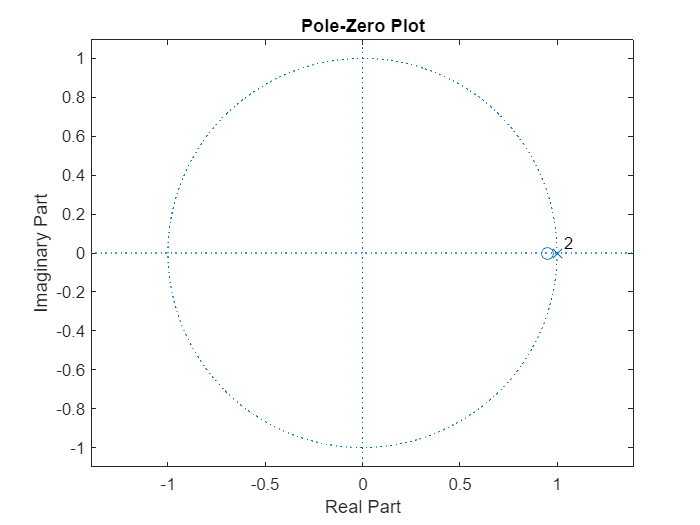

sys_d1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_d1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

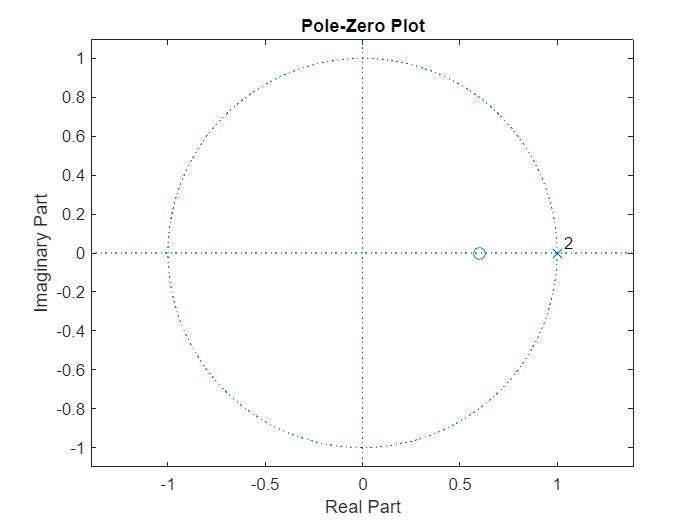

sys_d2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_d2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

% problem e
num = 8*z + (z - 1)^2;
den = 4*(z - 1)^2;
sys = T^2 / 2 * num / den

$$sys = \frac{T^{2}\,\left(8\,z+{\left(z-1\right)}^{2}\right)}{8\,{\left(z-1\right)}^{2}}$$

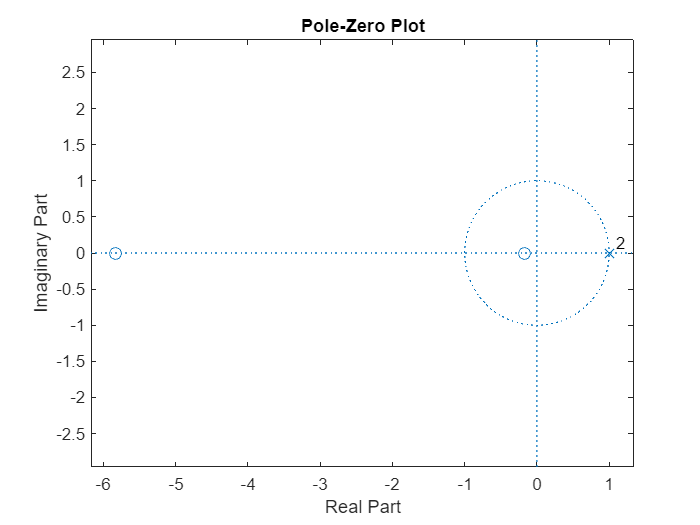

sys_e1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_e1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

sys_e2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_e2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

% problem f
num = T^2*(z + 1) - 2*T*(z - 1);
den = 2*(z - 1)^2;
sys = T^2 / 2 * num / den

$$sys = -\frac{T^{2}\,\left(2\,T\,\left(z-1\right)-T^{2}\,\left(z+1\right)\right)}{4\,{\left(z-1\right)}^{2}}$$

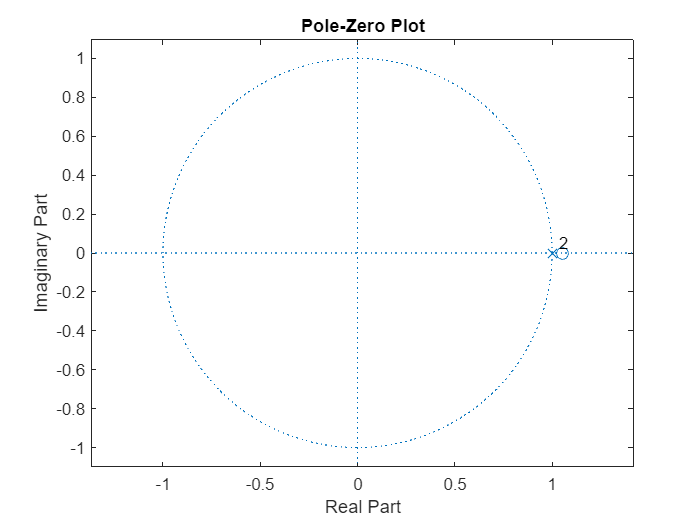

sys_f1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_f1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

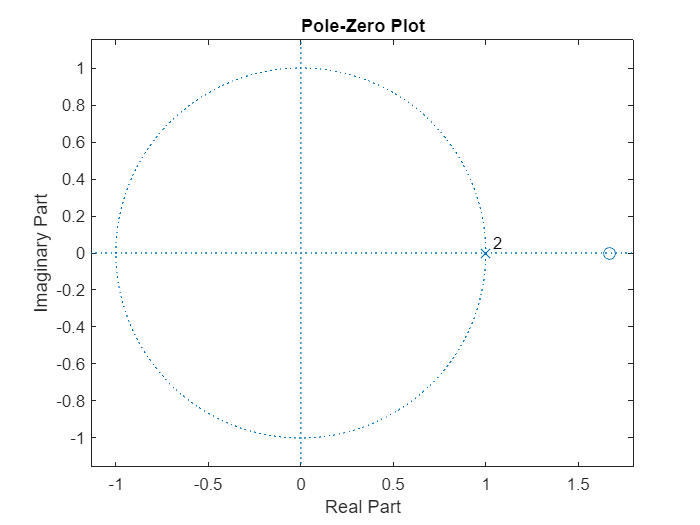

sys_f2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_f2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

% problem g
num = (z-1)*(2*(z - exp(-T))*(z - exp(-3*T)) - 3*exp(-0.5*T)*(z - 1)*(z - exp(-3*T)) + exp(-1.5*T)*(z - 1)*(z - exp(-T)));
den = z^2 * 2 * (z - 1)*(z - exp(-T))*(z - exp(-3*T));
sys = T^2 / 2 * num / den

$$sys = \frac{T^{2}\,\left(\left(z-{\mathrm{e}}^{-3\,T}\right)\,\left(2\,z-2\,{\mathrm{e}}^{-T}\right)-3\,{\mathrm{e}}^{-\frac{T}{2}}\,\left(z-{\mathrm{e}}^{-3\,T}\right)\,\left(z-1\right)+{\mathrm{e}}^{-\frac{3\,T}{2}}\,\left(z-{\mathrm{e}}^{-T}\right)\,\left(z-1\right)\right)}{4\,z^{2}\,\left(z-{\mathrm{e}}^{-T}\right)\,\left(z-{\mathrm{e}}^{-3\,T}\right)}$$

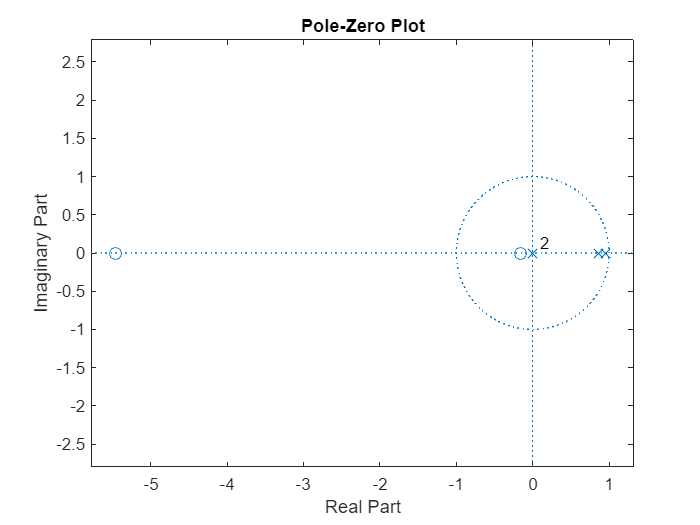

sys_g1 = subs(sys, T, 0.05);
[num, den]= numden(simplifyFraction(sys_g1));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)

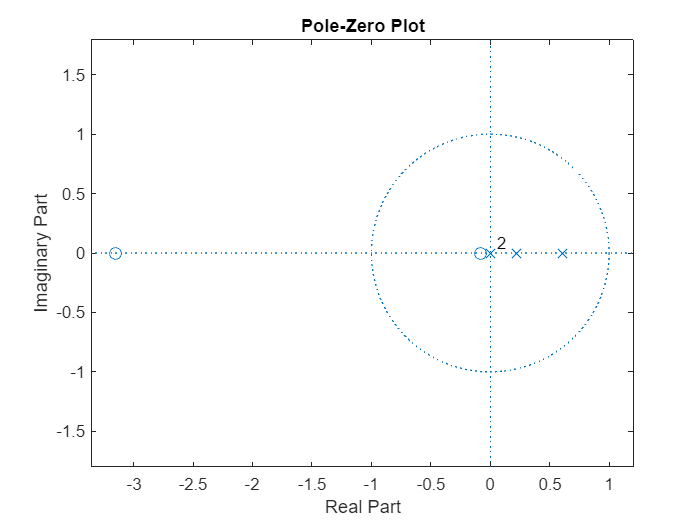

sys_g2 = subs(sys, T, 0.5);
[num, den]= numden(simplifyFraction(sys_g2));
num_roots = solve(num, z);
num_roots = double(num_roots);
den_roots = solve(den, z);
den_roots = double(den_roots);
zplane(num_roots, den_roots)